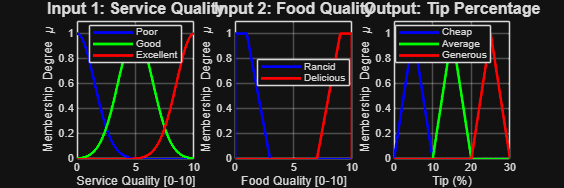

%% =========================================================
%  FUZZY MODELLING AND INFERENCE USING FUZZY RULE BASE
%  Example: Tip calculation (Service Quality + Food Quality -> Tip %)
% ==========================================================
clc; clear; close all;

%% ---- 1. DEFINE UNIVERSE OF DISCOURSE ----
x_service = linspace(0, 10, 1000);   % Service quality [0..10]
x_food    = linspace(0, 10, 1000);   % Food quality    [0..10]
x_tip     = linspace(0, 30, 1000);   % Tip percentage  [0..30]

%% ---- 2. MEMBERSHIP FUNCTIONS (Input 1: Service) ----
% Poor  - Gaussian MF
mf_service_poor   = gaussmf(x_service, [1.5  0]);
% Good  - Gaussian MF
mf_service_good   = gaussmf(x_service, [1.5  5]);
% Excellent - Gaussian MF
mf_service_exc    = gaussmf(x_service, [1.5 10]);

%% ---- 3. MEMBERSHIP FUNCTIONS (Input 2: Food) ----
% Rancid - Trapezoidal MF
mf_food_rancid    = trapmf(x_food, [0  0  1  3]);
% Delicious - Trapezoidal MF
mf_food_delicious = trapmf(x_food, [7  9 10 10]);

%% ---- 4. MEMBERSHIP FUNCTIONS (Output: Tip) ----
% Cheap   - Triangular MF
mf_tip_cheap  = trimf(x_tip, [0   5  10]);
% Average - Triangular MF
mf_tip_avg    = trimf(x_tip, [10 15  20]);
% Generous - Triangular MF
mf_tip_gen    = trimf(x_tip, [20 25  30]);

%% ---- 5. PLOT ALL MEMBERSHIP FUNCTIONS ----
figure('Name','Fuzzy Membership Functions','NumberTitle','off',...
       'Position',[100 100 1200 400]);

subplot(1,3,1);
plot(x_service, mf_service_poor,  'b-', 'LineWidth',2); hold on;
plot(x_service, mf_service_good,  'g-', 'LineWidth',2);
plot(x_service, mf_service_exc,   'r-', 'LineWidth',2);
title('Input 1: Service Quality','FontSize',12,'FontWeight','bold');
xlabel('Service Quality [0-10]'); ylabel('Membership Degree \mu');
legend('Poor','Good','Excellent','Location','best');
grid on; ylim([0 1.1]);

subplot(1,3,2);
plot(x_food, mf_food_rancid,    'b-', 'LineWidth',2); hold on;
plot(x_food, mf_food_delicious, 'r-', 'LineWidth',2);
title('Input 2: Food Quality','FontSize',12,'FontWeight','bold');
xlabel('Food Quality [0-10]'); ylabel('Membership Degree \mu');
legend('Rancid','Delicious','Location','best');
grid on; ylim([0 1.1]);

subplot(1,3,3);
plot(x_tip, mf_tip_cheap, 'b-', 'LineWidth',2); hold on;
plot(x_tip, mf_tip_avg,   'g-', 'LineWidth',2);
plot(x_tip, mf_tip_gen,   'r-', 'LineWidth',2);
title('Output: Tip Percentage','FontSize',12,'FontWeight','bold');
xlabel('Tip (%)'); ylabel('Membership Degree \mu');
legend('Cheap','Average','Generous','Location','best');
grid on; ylim([0 1.1]);


%% ---- 6. CRISP INPUTS (Fuzzification) ----
service_val = 6.5;   % User-defined crisp input
food_val    = 8.0;   % User-defined crisp input

fprintf('\n==============================================\n');

fprintf('  FUZZY INFERENCE SYSTEM - MAMDANI METHOD\n');

  FUZZY INFERENCE SYSTEM - MAMDANI METHOD


fprintf('==============================================\n');

fprintf('  Crisp Input: Service Quality = %.1f\n', service_val);

  Crisp Input: Service Quality = 6.5


fprintf('  Crisp Input: Food Quality    = %.1f\n', food_val);

  Crisp Input: Food Quality    = 8.0


fprintf('==============================================\n\n');


%% ---- 7. FUZZIFICATION ----
% Compute membership degrees for each linguistic term at crisp input
mu_service_poor  = gaussmf(service_val, [1.5  0]);
mu_service_good  = gaussmf(service_val, [1.5  5]);
mu_service_exc   = gaussmf(service_val, [1.5 10]);

mu_food_rancid    = trapmf(food_val, [0  0  1  3]);
mu_food_delicious = trapmf(food_val, [7  9 10 10]);

fprintf('--- FUZZIFICATION ---\n');

--- FUZZIFICATION ---


fprintf('  mu(Service = Poor)      = %.4f\n', mu_service_poor);

  mu(Service = Poor)      = 0.0001


fprintf('  mu(Service = Good)      = %.4f\n', mu_service_good);

  mu(Service = Good)      = 0.6065


fprintf('  mu(Service = Excellent) = %.4f\n', mu_service_exc);

  mu(Service = Excellent) = 0.0657


fprintf('  mu(Food = Rancid)       = %.4f\n', mu_food_rancid);

  mu(Food = Rancid)       = 0.0000


fprintf('  mu(Food = Delicious)    = %.4f\n\n', mu_food_delicious);

  mu(Food = Delicious)    = 0.5000




%% ---- 8. FUZZY RULE BASE (Mamdani) ----
%
%  Rule 1: IF service is poor   OR  food is rancid    THEN tip is cheap
%  Rule 2: IF service is good                          THEN tip is average
%  Rule 3: IF service is excellent OR food is delicious THEN tip is generous

% Firing strengths (using MIN for AND, MAX for OR)
alpha1 = max(mu_service_poor,  mu_food_rancid);      % Rule 1: OR
alpha2 = mu_service_good;                             % Rule 2: AND only service
alpha3 = max(mu_service_exc,   mu_food_delicious);   % Rule 3: OR

fprintf('--- RULE EVALUATION (Firing Strengths) ---\n');

--- RULE EVALUATION (Firing Strengths) ---


fprintf('  Rule 1 (Service=Poor   OR  Food=Rancid)   -> alpha = %.4f -> Tip=Cheap\n',   alpha1);

  Rule 1 (Service=Poor   OR  Food=Rancid)   -> alpha = 0.0001 -> Tip=Cheap


fprintf('  Rule 2 (Service=Good)                      -> alpha = %.4f -> Tip=Average\n', alpha2);

  Rule 2 (Service=Good)                      -> alpha = 0.6065 -> Tip=Average


fprintf('  Rule 3 (Service=Exc    OR  Food=Delicious) -> alpha = %.4f -> Tip=Generous\n\n', alpha3);

  Rule 3 (Service=Exc    OR  Food=Delicious) -> alpha = 0.5000 -> Tip=Generous




%% ---- 9. IMPLICATION (Clip each output MF by firing strength) ----
implied_cheap   = min(alpha1, mf_tip_cheap);
implied_avg     = min(alpha2, mf_tip_avg);
implied_gen     = min(alpha3, mf_tip_gen);

%% ---- 10. AGGREGATION (Union = MAX of all implied MFs) ----
aggregated = max(max(implied_cheap, implied_avg), implied_gen);

%% ---- 11. DEFUZZIFICATION (Centroid / Center of Gravity) ----
tip_crisp = sum(x_tip .* aggregated) / sum(aggregated);

fprintf('--- DEFUZZIFICATION (Centroid Method) ---\n');

--- DEFUZZIFICATION (Centroid Method) ---


fprintf('  Crisp Output: Tip = %.2f %%\n\n', tip_crisp);

  Crisp Output: Tip = 19.70 %



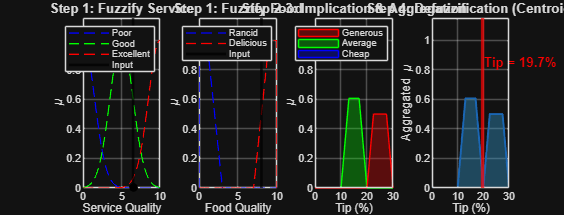


%% ---- 12. PLOT INFERENCE PROCESS ----
figure('Name','Mamdani Fuzzy Inference Process','NumberTitle','off',...
       'Position',[100 550 1100 420]);

subplot(1,4,1);
plot(x_service, mf_service_poor,  'b--', 'LineWidth',1); hold on;
plot(x_service, mf_service_good,  'g--', 'LineWidth',1);
plot(x_service, mf_service_exc,   'r--', 'LineWidth',1);
xline(service_val, 'k-', 'LineWidth',2);
plot(service_val, 0, 'ko', 'MarkerSize',6, 'MarkerFaceColor','k');
title('Step 1: Fuzzify Service','FontWeight','bold','FontSize',10);
xlabel('Service Quality'); ylabel('\mu'); grid on; ylim([0 1.15]);
legend('Poor','Good','Excellent','Input','Location','NE','FontSize',7);

subplot(1,4,2);
plot(x_food, mf_food_rancid,    'b--', 'LineWidth',1); hold on;
plot(x_food, mf_food_delicious, 'r--', 'LineWidth',1);
xline(food_val,'k-','LineWidth',2);
title('Step 1: Fuzzify Food','FontWeight','bold','FontSize',10);
xlabel('Food Quality'); ylabel('\mu'); grid on; ylim([0 1.15]);
legend('Rancid','Delicious','Input','Location','NE','FontSize',7);

subplot(1,4,3);
area(x_tip, implied_cheap, 'FaceColor','b','FaceAlpha',0.3,'EdgeColor','b'); hold on;
area(x_tip, implied_avg,   'FaceColor','g','FaceAlpha',0.3,'EdgeColor','g');
area(x_tip, implied_gen,   'FaceColor','r','FaceAlpha',0.3,'EdgeColor','r');
title('Step 2-3: Implication & Aggregation','FontWeight','bold','FontSize',10);
xlabel('Tip (%)'); ylabel('\mu'); grid on; ylim([0 1.15]);
legend('Cheap','Average','Generous','Location','NE','FontSize',7);

subplot(1,4,4);
area(x_tip, aggregated, 'FaceColor',[0.2 0.6 0.8],'FaceAlpha',0.4,'EdgeColor',[0.1 0.4 0.7],'LineWidth',1.5);
hold on;
xline(tip_crisp, 'r-', 'LineWidth', 2.5);
text(tip_crisp + 0.4, 0.85, sprintf('Tip = %.1f%%', tip_crisp), ...
     'Color','r','FontSize',10,'FontWeight','bold');
title('Step 4: Defuzzification (Centroid)','FontWeight','bold','FontSize',10);
xlabel('Tip (%)'); ylabel('Aggregated \mu'); grid on; ylim([0 1.15]);


%% ---- 13. SURFACE PLOT (Full Input Space) ----
fprintf('Computing output surface over full input space...\n');

Computing output surface over full input space...


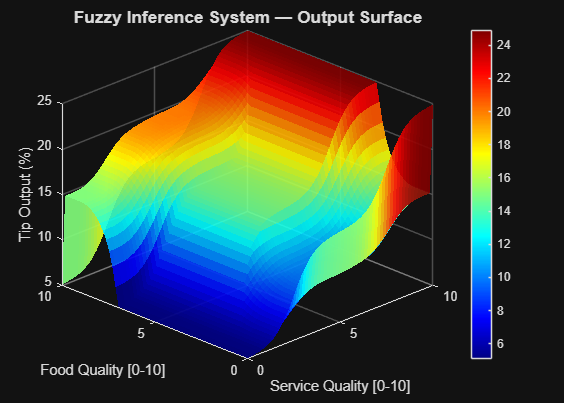

sv = linspace(0,10,60);
fv = linspace(0,10,60);
[SV, FV] = meshgrid(sv, fv);
TIP_OUT = zeros(size(SV));

for i = 1:numel(sv)
    for j = 1:numel(fv)
        s = sv(i); f = fv(j);
        ms_p = gaussmf(s, [1.5  0]);
        ms_g = gaussmf(s, [1.5  5]);
        ms_e = gaussmf(s, [1.5 10]);
        mf_r = trapmf(f,  [0 0 1 3]);
        mf_d = trapmf(f,  [7 9 10 10]);
        a1 = max(ms_p, mf_r);
        a2 = ms_g;
        a3 = max(ms_e, mf_d);
        ic = min(a1, mf_tip_cheap);
        ia = min(a2, mf_tip_avg);
        ig = min(a3, mf_tip_gen);
        agg = max(max(ic, ia), ig);
        if sum(agg) > 0
            TIP_OUT(j,i) = sum(x_tip .* agg) / sum(agg);
        else
            TIP_OUT(j,i) = 0;
        end
    end
end

figure('Name','Fuzzy System Surface View','NumberTitle','off',...
       'Position',[100 100 700 500]);
surf(SV, FV, TIP_OUT, 'EdgeColor','none','FaceAlpha',0.9);
colormap(jet); colorbar;
xlabel('Service Quality [0-10]','FontSize',11);
ylabel('Food Quality [0-10]','FontSize',11);
zlabel('Tip Output (%)','FontSize',11);
title('Fuzzy Inference System — Output Surface','FontSize',13,'FontWeight','bold');
view([-45 30]); grid on;


fprintf('\n==============================================\n');

fprintf('  SUMMARY\n');

  SUMMARY


fprintf('  Service Quality = %.1f, Food Quality = %.1f\n', service_val, food_val);

  Service Quality = 6.5, Food Quality = 8.0


fprintf('  Recommended Tip = %.2f %%\n', tip_crisp);

  Recommended Tip = 19.70 %


fprintf('==============================================\n');


%% ---- HELPER FUNCTIONS ----
function y = gaussmf(x, params)
    sigma = params(1); c = params(2);
    y = exp(-0.5 * ((x - c) / sigma).^2);
end

function y = trimf(x, params)
    a = params(1); b = params(2); c = params(3);
    y = max(0, min((x-a)/(b-a+eps), (c-x)/(c-b+eps)));
end

function y = trapmf(x, params)
    a = params(1); b = params(2); c = params(3); d = params(4);
    y = max(0, min(min((x-a)/(b-a+eps), 1), (d-x)/(d-c+eps)));
end